clc
% importing files %
[fnames, fpath] = uigetfile('*.csv','MultiSelect', 'on');

if isequal(fnames,0)
    disp('user cancelled file selection')
else
    if ischar(fnames)
        fnames = {fnames};
    end
    data = cell(1,numel(fnames));
    for i = 1:numel(fnames)
        fullPath = fullfile(fpath,fnames{i});
        data{i} = readtable(fullPath);
        fprintf('file %d imported! processing...\n', i);
    end
end

file 1 imported! processing...
file 2 imported! processing...
file 3 imported! processing...



% a little data processing %
t1 = (data1.ts_ms - data1.ts_ms(1)) / 1000;
imu_t1 = data1.imu_temp_c;
esp_t1 =  data1.esp32_temp_c;
data1.az_g;
disp('first file processed!')

first file processed!



t2 = (data2.ts_ms - data2.ts_ms(1)) / 1000;
imu_t2 = data2.imu_temp_c;
esp_t2 =  data2.esp32_temp_c;
data2.az_g;
disp('second file processed!')

second file processed!



t3 = (data3.ts_ms - data3.ts_ms(1)) / 1000;
imu_t3 = data3.imu_temp_c;
esp_t3 =  data3.esp32_temp_c;
data3.az_g;
disp('third file processed!')

third file processed!


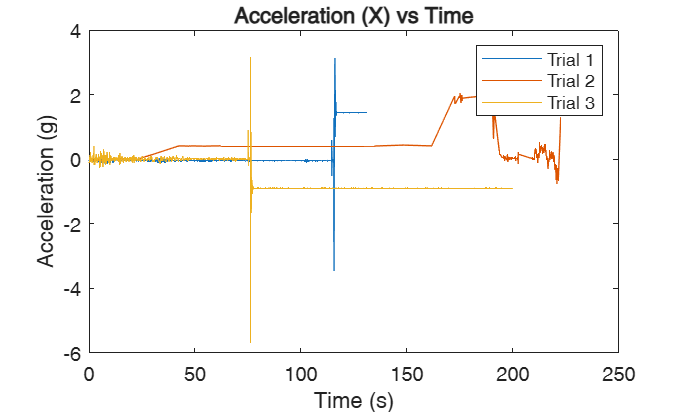


% Acceleration
% x %
figure;
plot(t1, data1.ax_g, t2, data2.ax_g, t3, data3.ax_g);
legend('Trial 1','Trial 2','Trial 3');
xlabel('Time (s)');
ylabel('Acceleration (g)');
title('Acceleration (X) vs Time');

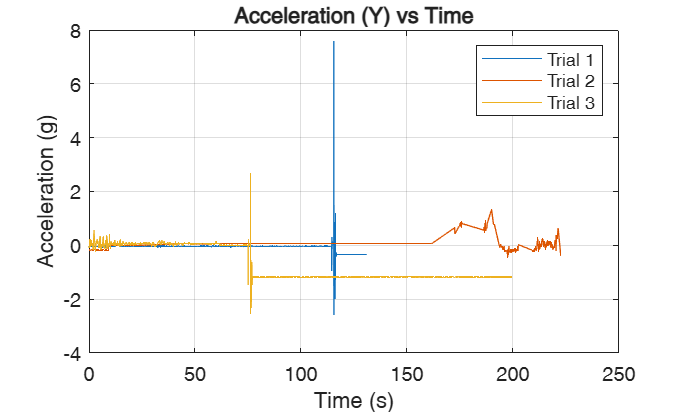

% y %
figure;
plot(t1, data1.ay_g, t2, data2.ay_g, t3, data3.ay_g);
legend('Trial 1','Trial 2','Trial 3');
xlabel('Time (s)');
ylabel('Acceleration (g)');
title('Acceleration (Y) vs Time');
grid on;

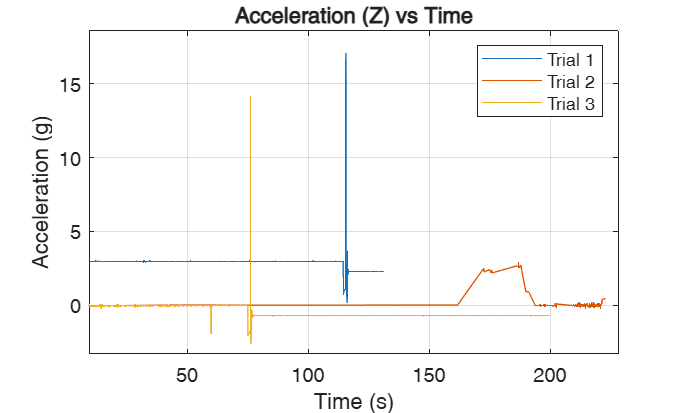

% z %
figure;
plot(t1, data1.az_g*-1, t2, data2.az_g, t3, data3.az_g*-1);
legend('Trial 1','Trial 2','Trial 3');
xlabel('Time (s)');
ylabel('Acceleration (g)');
title('Acceleration (Z) vs Time');
grid on;


% Gyroscope
figure;
plot(t, data.gx_dps, t, data.gy_dps, t, data.gz_dps);

Dot indexing is not supported for variables of this type.

xlabel('Time (s)');
ylabel('Angular Velocity (deg/s)');
title('Gyroscope vs Time');
legend('gx','gy','gz');
grid on;

figure
a_mag1 = sqrt(data1.ax_g.^2 + data1.ay_g.^2 + data1.az_g.^2);
a_mag2 = sqrt(data2.ax_g.^2 + data2.ay_g.^2 + data2.az_g.^2);
a_mag3 = sqrt(data3.ax_g.^2 + data3.ay_g.^2 + data3.az_g.^2);
plot(t,a_mag)
xlabel('Time (s)');
ylabel('Accel. Magnitude (g)');
title('Accel. Magnitude vs Time');
% EDIT XLIM HERE
% xlim([22 25])

figure
plot(t,imu_t)
xlabel('Time (s)');
ylabel('Temperature (C)')
title('IMU Temperature vs Time');

figure
plot(t,esp_t)
xlabel('Time (s)');
ylabel('Temperature (C)')
title('ESP Temperature vs Time');
